### Communication Systems I - Fall 1399

### Computer Assignment #1

**Question 1:**

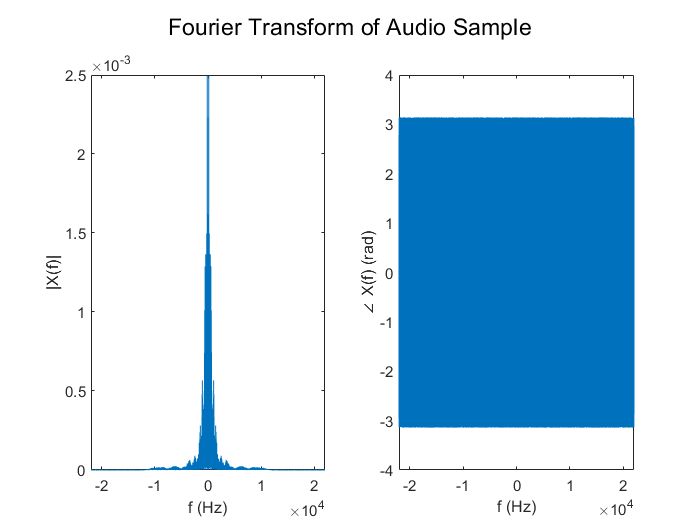

close all;
clear;
clc;

%read audio file
[x, Fs] = audioread("sample.wav");

%calculate fourier transform            
Ts = 1/Fs;            % Sampling period       
L = length(x);        % Length of signal
t = (0:L-1)*Ts;       % Time vector

X = fft(x);
f = (0:L-1)*(Fs/L);
Xshift = fftshift(X);
fshift = (-L/2:L/2-1)*(Fs/L);

%plot fourier transform
figure;
subplot(1,2,1);
plot(fshift, abs(Xshift)/L);
% axis([-1000 1000 0 3e-3]);
ylabel("|X(f)|");
xlabel("f (Hz)");
subplot(1,2,2);
plot(fshift, angle(Xshift));
% axis([-1 1 -6e-6 6e-6]);
ylabel('\angle X(f) (rad)');
xlabel("f (Hz)");
suptitle("Fourier Transform of Audio Sample");

**Question 2:**

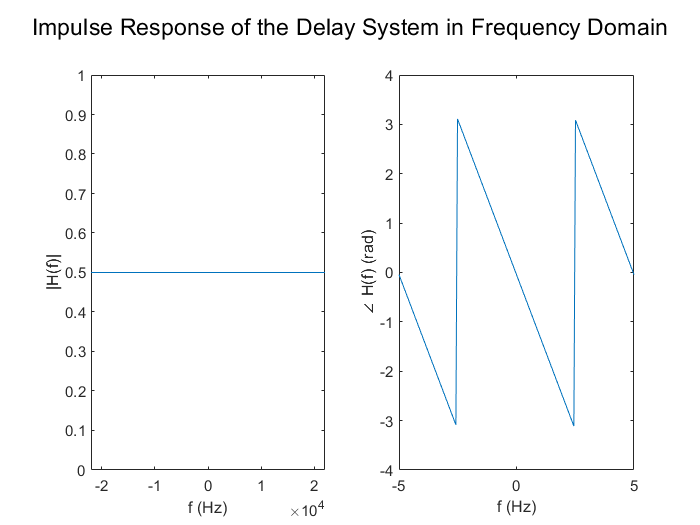

%creat H(f)
H = 0.5*exp(-1i*2*pi*(1/5)*f);
Hshift = fftshift(H);

%plot H(f)
figure;
subplot(1,2,1);
plot(fshift, abs(Hshift));
axis([-2.2e4 2.2e4 0 1]);
ylabel("|H(f)|");
xlabel("f (Hz)");
subplot(1,2,2);
plot(fshift, angle(Hshift));
axis([-5 5 -4 4]);
ylabel('\angle H(f) (rad)');
xlabel("f (Hz)");
suptitle("Impulse Response of the Delay System in Frequency Domain");

This $H\left(f\right)$induces no distortion, just time delay.

**Question 3:**

%create H(f)
H = ones(size(f)) + (0.5*exp(-1i*2*pi*(1/5)*f));

%obtain output in frequency domain
Y = X .* (H.');

%transform Y(f) to y(t)
y = ifft(Y);

To hear y(t), run below line:

%sound(real(y), Fs);

$\Longrightarrow$y(t) is the same as x(t), except it has an echo.


$$y\left(t\right)=x\left(t\right)+0\ldotp 5\;x\left(t-\frac{1}{5}\right)$$


**Question 4:**

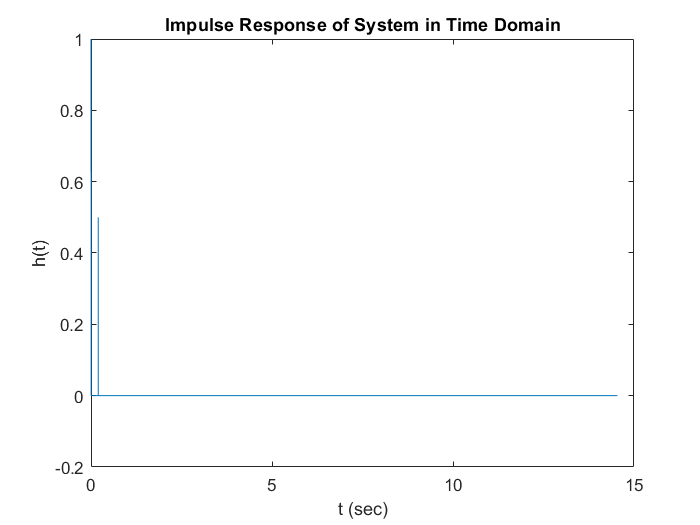

h = ifft(H);
figure;
plot(t, real(h));
title("Impulse Response of System in Time Domain");
ylabel("h(t)");
xlabel("t (sec)");

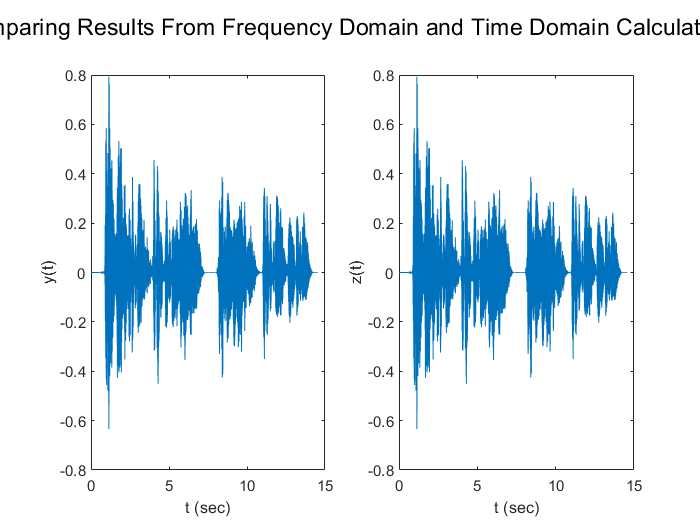


z = conv(x, h);
%sound(real(z), Fs);

figure;
subplot(1,2,1);
plot(t, real(y));
ylabel("y(t)");
xlabel("t (sec)");
subplot(1,2,2);
plot(t, real(z(1:length(t))));
ylabel("z(t)");
xlabel("t (sec)");
suptitle("Comparing Results From Frequency Domain and Time Domain Calculations");

**Question 5:**

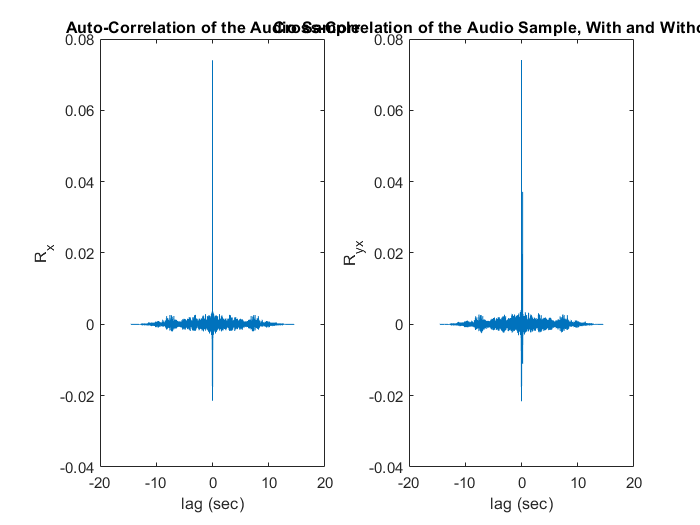

[Rx, lagx] = xcorr(x,x);
[Ryx, lagyx] = xcorr(real(y),x);

figure;
subplot(1,2,1);
plot(lagx*Ts, Rx*Ts);
title("Auto-Correlation of the Audio Sample");
ylabel("R_x");
xlabel("lag (sec)");
subplot(1,2,2);
plot(lagyx*Ts, Ryx*Ts);
title("Cross-Correlation of the Audio Sample, With and Without Echo ");
ylabel("R_{yx}");
xlabel("lag (sec)");

**Question 6:**

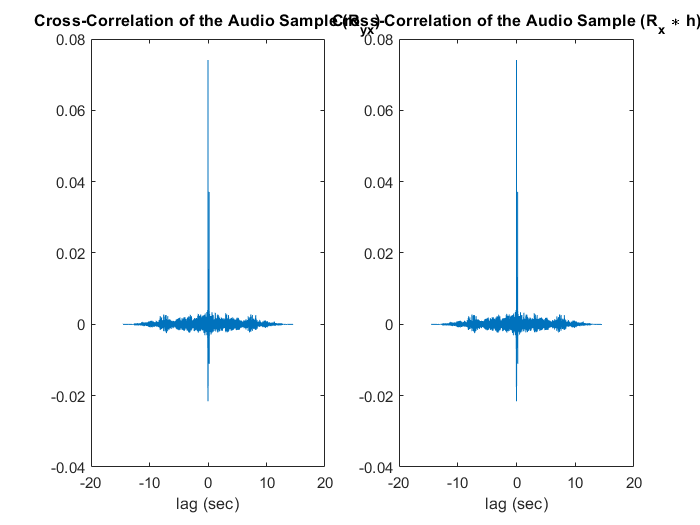

%calculate Rx * h
Ryx_c = conv(Rx, real(h));
Ryx_c = Ryx_c(1:length(Ryx));

%plot and compare
figure;
subplot(1,2,1);
plot(lagyx*Ts, Ryx*Ts);
title("Cross-Correlation of the Audio Sample (R_{yx})");
xlabel("lag (sec)");
subplot(1,2,2);
plot(lagyx*Ts, Ryx_c*Ts);
title("Cross-Correlation of the Audio Sample (R_x \ast h)");
xlabel("lag (sec)");


%find Mean Square Error
MSE_R = mean((abs(Ryx - Ryx_c)).^2);
disp(['MSE = ', num2str(MSE_R*Ts)]);

MSE = 1.8322e-10


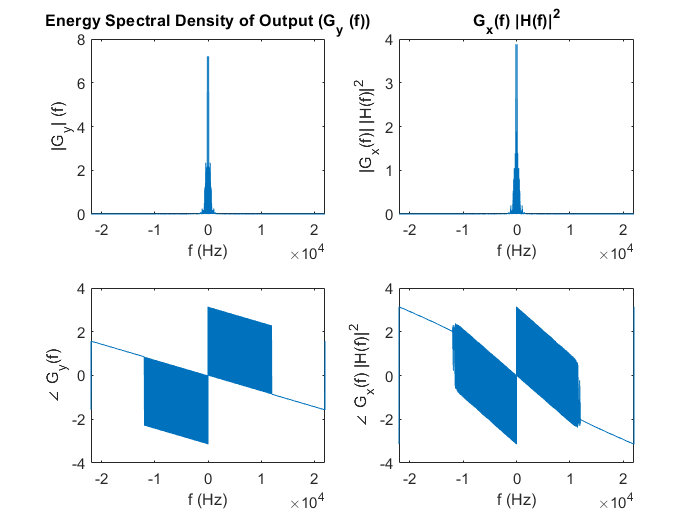


%find Gy
[Ry, lagy] = xcorr(real(y),real(y),floor(length(y)/2));
Gy = ifft(Ry);

%find Gx . |H|^2
a = floor((length(Rx)-L)/2);
Rx = Rx(a+L-1:-1:a);
Gx = ifft(Rx);
Gy_c = Gx .* (abs((H.')).^2);

%plot and compare
figure;
subplot(2,2,1);
plot(fshift, abs(fftshift(Gy)));
title("Energy Spectral Density of Output (G_y (f))");
ylabel("|G_y| (f)")
xlabel("f (Hz)");
subplot(2,2,3);
plot(fshift, angle(fftshift(Gy)));
ylabel("\angle G_y(f)");
xlabel("f (Hz)");
subplot(2,2,2);
plot(fshift, abs(fftshift(Gx)));
title("G_x(f) |H(f)|^2");
ylabel("|G_x(f)| |H(f)|^2")
xlabel("f (Hz)");
subplot(2,2,4);
plot(fshift, angle(fftshift(Gx)));
ylabel("\angle G_x(f) |H(f)|^2")
xlabel("f (Hz)");


%find Mean Square Error
MSE_G = mean((abs(Gy - Gy_c)).^2);
disp(['MSE = ', num2str(MSE_G*Ts)]);

MSE = 5.7124e-10


**Question 7:**

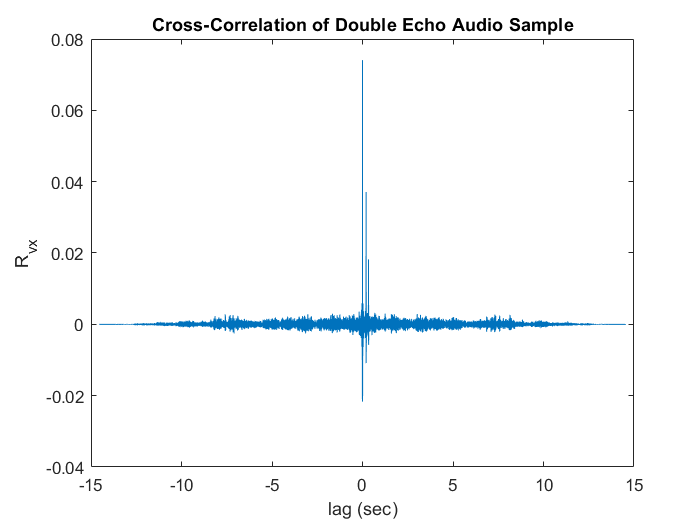

%design H2(f)
H2 = 1 + (0.5.*exp(-1i*2*pi*(1/5).*f)) + (0.25.*exp(-1i*2*pi*(1/3).*f));

%obtain output in frequency domain
V = X .* (H2.');
v = ifft(V);

%save audio
audiowrite("echoed.wav",real(v),Fs);

%plot correlation
[Rvx, lagvx] = xcorr(real(v), x);
figure;
plot(lagvx*Ts, Rvx*Ts);
title("Cross-Correlation of Double Echo Audio Sample");
ylabel("R_{vx}");
xlabel("lag (sec)");

### Good Luck :)